# **Event-Based Controller**

**...**

clc; clear all; close all;
starter_code;

a = 0.9;
mu = 0.8;
epsilon = 0.1;

x_0 = [ -0.3827;
         0.9239;
         2.2253;
         3.0107;
         0.5236;
         0.8653;
         0.3584;
        -1.0957;
        -2.3078;
         2.0323];

## [HW5] Input-Output Linearizing Controller

### Calculate u and v

syms x_1 x_2 real

dy = [dq3;
      dq1+dq2+2*dq3];

% controller parameters
Phi_a = simplify(x_1+1/(2-a)*sign(x_2)*abs(x_2)^(2-a));
Psi_a = simplify(-sign(x_2)*abs(x_2)^a-sign(Phi_a)*abs(Phi_a)^(a/(2-a)));

v = simplify([1/(epsilon^2) * subs(Psi_a,[x_1 x_2],[y(1) epsilon*dy(1)]);
     1/(epsilon^2) * subs(Psi_a,[x_1 x_2],[y(2) epsilon*dy(2)])]);
u = simplify(LgLfy\(-Lf2y+v));

fun_u = matlabFunction(u);
fun_f_s = matlabFunction(f_s);
fun_g_s = matlabFunction(g_s);
fun_dqPlus = matlabFunction(dqPlus);
fun_FSt = matlabFunction(FSt);

%fun_u_current = @(dq1,dq2,dq3,q1,q2,q3) fun_u(dq1,dq2,dq3,q1,q2,q3,pi/1.5)

## [HW6] 

### Simulation

% first guess: 
% theta_3_d = pi/6;


x_0 = [ -0.3827;
         0.9239;
         2.2253;
         3.0107;
         0.5236;
         0.8653;
         0.3584;
        -1.0957;
        -2.3078;
         2.0323];

options = odeset('Events', @three_link_event);

theta_3_d_controller = [(pi/6)];

fun_u_current = @(dq1,dq2,dq3,q1,q2,q3) fun_u(dq1,dq2,dq3,q1,q2,q3,theta_3_d_controller(end));
[t,x] = ode45(@(t,x) three_link_dynamics(t,x,fun_u_current ,fun_f_s,fun_g_s), [0:0.1:10] , x_0, options);t_sol = t;
q_sol = x;
v_avg = [(x(end,1)-x(1,1))/(t(end)-t(1))];
% theta_3_d_controller = event_based_controller(v_avg(end))
% fun_u_current = @(dq1,dq2,dq3,q1,q2,q3) fun_u(dq1,dq2,dq3,q1,q2,q3,theta_3_d_controller)

x_0 = three_link_impactdynamics(x(end,:)',fun_dqPlus,R);

error = [0.5-v_avg(end)];
derror= [0];
sumerror = [sum(error)];
for step = 2:100

    % https://www.thorlabs.com/newgrouppage9.cfm?objectgroup_id=9013#:~:text=To%20tune%20your%20PID%20controller,to%20roughly%20half%20this%20value.

% good values for: theta_3_d_controller = [(pi/8)];
%     Kp = 0.035;
%     Kd = 0.076;
%     Ki = 0.000001;

%     Kp = 0.026;
%     Kd = 0.02;
%     Kp = 0.05;
%     Kd = 0.117;
%     Ki =0.0001;

    Kp = 0.049;
    Kd = 0.07;
    Ki = 0.0000001;

    control_input = event_based_controller(Kp,Kd,Ki, error(end), derror(end), sumerror(end));
    theta_3_d_controller = [theta_3_d_controller;
                            theta_3_d_controller(end)+control_input];
    fun_u_current = @(dq1,dq2,dq3,q1,q2,q3) fun_u(dq1,dq2,dq3,q1,q2,q3,theta_3_d_controller(end));

    length_prev = t_sol(end);
    [t,x] = ode45(@(t, x)three_link_dynamics(t,x,fun_u_current,fun_f_s,fun_g_s), [length_prev:0.1:length_prev+10] ,x_0,options);
    length(t);
    t_sol = [t_sol;t(2:end)];
    q_sol = [q_sol;x(2:end,:)];
    v_avg = [v_avg;(x(end,1)-x(1,1))/(t(end)-t(1))];

    % Apply impact dynamics
    x_0 = three_link_impactdynamics(x(end,:)',fun_dqPlus,R);
    error = [error;0.5-v_avg(end)];
    derror = [derror;(error(end)-error(end-1))];
    % divide by time dif
    sumerror = [sumerror;sum(error)];


end
t_sol = t_sol';
q_sol = q_sol';

for i = 1:length(v_avg)
    if all(round(v_avg(i:end),4) == 0.5)
        disp("Finished after "+ i +" steps!");
        break
    end
end

Finished after 25 steps!


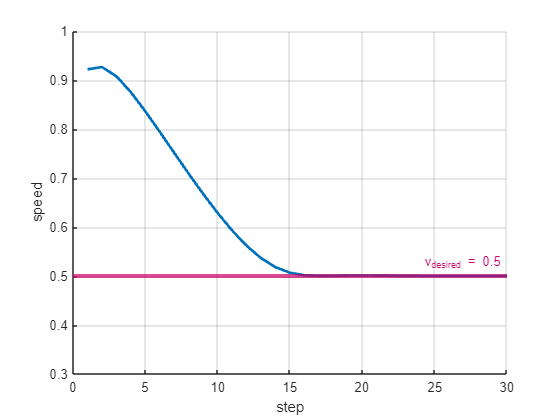

clf;
figure(1)
hold on
grid on
plot(v_avg,'LineWidth',2);
yline(0.5,'-','v_{desired} = 0.5','LineWidth',3,Color = [.80 0 .40]);
ylim([0.3,1]);
xlim([0,30]);
xlabel('step');
ylabel('speed');

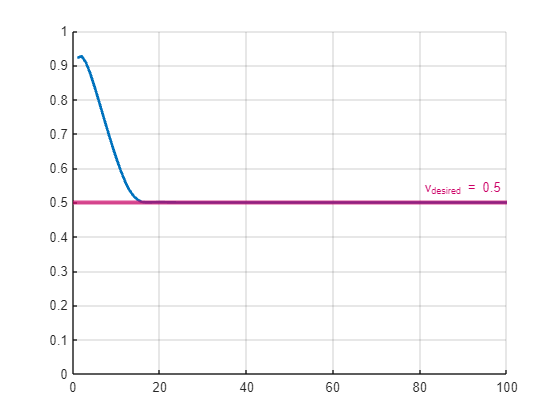

clf;
figure(1234)
hold on
grid on
plot(v_avg,'LineWidth',2);
yline(0.5,'-','v_{desired} = 0.5','LineWidth',3,Color = [.80 0 .40]);
ylim([0,1]);

### Animate

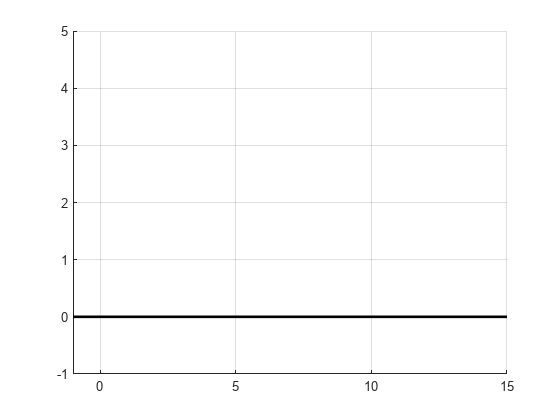

animateThreeLink(t_sol', q_sol')

### theta_1 vs dtheta_1

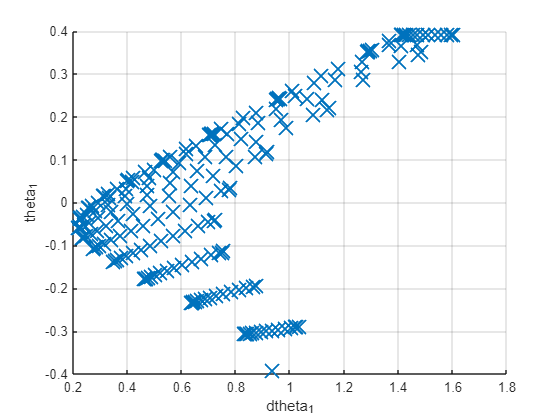

clf;
figure(2)
hold on;
grid on;

    theta_1 = q_sol(3,:)+q_sol(5,:)-pi;
    dtheta_1 = q_sol(8,:)+q_sol(10,:);

plot(dtheta_1,theta_1,'x','LineWidth', 1.4, MarkerSize=15);

xlabel('dtheta_1');
ylabel('theta_1');

### u1 & u2 vs time

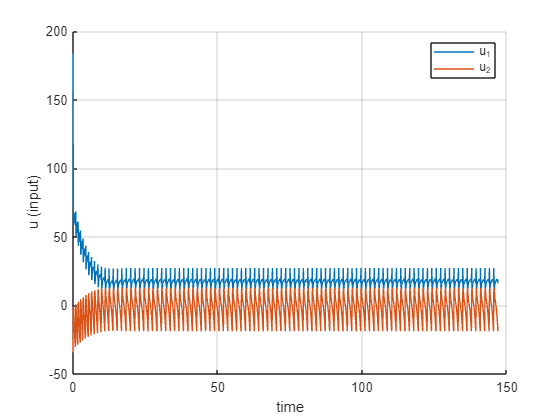

clf;
figure(3)
hold on;
grid on;

    % fun_u(dq1,dq2,dq3,q1,q2,q3)
    u_sol = fun_u_current(q_sol(8,:),q_sol(9,:),q_sol(10,:),q_sol(3,:),q_sol(4,:),q_sol(5,:));
    
plot(t_sol,u_sol(1,:));
plot(t_sol,u_sol(2,:))

xlabel('time');
ylabel('u (input)');
legend('u_1','u_2');

### F_st vs time

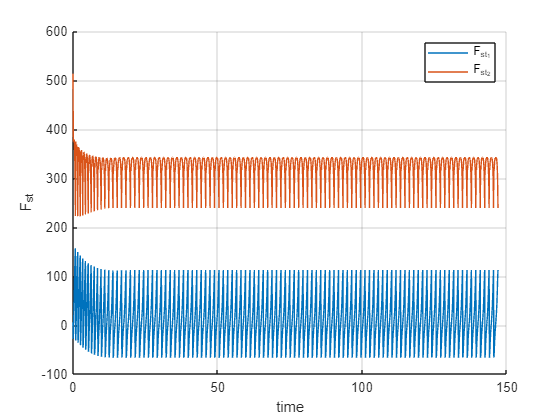

clf;
figure(4)
hold on;
grid on;

    % fun_u(dq1,dq2,dq3,q1,q2,q3,u1,u2)
    Fst_sol = fun_FSt(q_sol(8,:),q_sol(9,:),q_sol(10,:),q_sol(3,:),q_sol(4,:),q_sol(5,:),u_sol(1,:),u_sol(2,:));

plot(t_sol,Fst_sol(1,:));
plot(t_sol,Fst_sol(2,:));

xlabel('time');
ylabel('F_{st}');
legend('F_{st_1}','F_{st_2}');

### Vertical Component of F_st

clf;
figure(5);
hold on;
grid on;

    F_st_horizontal = Fst_sol(1,:);
    F_st_vertical = Fst_sol(2,:);

if (all(F_st_vertical>=0))
    disp("Ground is NOT pulling the robot. (Program seems to be running fine)");
else
    disp("ERROR: Ground is pulling the robot.")
end

Ground is NOT pulling the robot. (Program seems to be running fine)


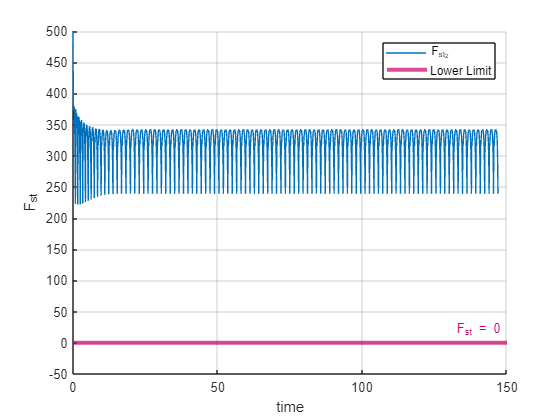


plot(t_sol,F_st_vertical);
yline(0,'-','F_{st} = 0','LineWidth',3,Color = [.80 0 .40])
ylim([-50,500])

xlabel('time');
ylabel('F_{st}');
legend('F_{st_2}','Lower Limit');

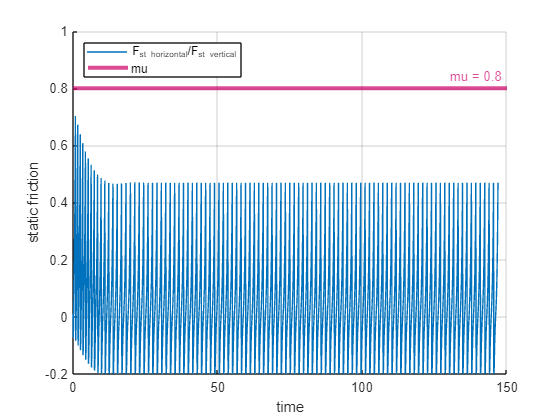

clf;
figure(6);
hold on;
grid on;

    static_friction = F_st_horizontal./F_st_vertical;

plot(t_sol,static_friction);
yline(mu,'-','mu = 0.8','LineWidth',3,Color = [.80 0 .40])
ylim([-.2,1])


xlabel('time');
ylabel('static friction');
legend('F_{st horizontal}/F_{st vertical}','mu','Location','northwest');

if (all(abs(static_friction)<mu))
    disp("Robot not slipping");
else
    disp("Robot slipping")
end

Robot not slipping


### Functions

function theta_3_d_controller = event_based_controller(Kp,Kd,Ki, error, derror, sumerror)
%     if length(error)>=2
%         theta_3_d_controller = error*Kp + derror*Kd;
%     else
%         % v_d_avg = 0.5;
%         theta_3_d_controller = error*Kp;
%     end
    theta_3_d_controller = error*Kp + derror*Kd + sumerror*Ki;
end

function [value, isterminal, direction] = three_link_event(t,x)
    % theta1 = pi/8
    value = x(5)+x(3)-pi-pi/8;
    isterminal = 1;
    % -ve to +ve crossing
    direction = +1;
end

function dx = three_link_dynamics(t,x,u,f_s,g_s)
    f_s = f_s(x(8),x(9),x(10),x(6),x(7),x(3),x(4),x(5));
    g_s = g_s(x(3),x(4),x(5));
    u   = u(x(8),x(9),x(10),x(3),x(4),x(5));
    dx  = f_s+g_s*u;
end

function xplus =three_link_impactdynamics(xminus,dqPlus,R)
    xplus         = zeros(10,1);
    xplus(1:5,1)  = R*xminus(1:5,1);
    xplus(6:10,1) = R*dqPlus(xminus(8),xminus(9),xminus(10) ...
                    ,xminus(6),xminus(7) ...
                    ,xminus(3),xminus(4),xminus(5));
end